# Brillo y contraste de una imagen

## Brillo

El **brillo** de una imagen se refiere al **nivel medio de intensidad** de sus píxeles.

- En imágenes en escala de grises, corresponde a qué tan **clara u oscura** se percibe la imagen en su totalidad.

- Matemáticamente, suele asociarse con el **valor promedio** de los niveles de gris.

- En procesamiento médico, ajustar el brillo ayuda a resaltar estructuras cuando la imagen es demasiado oscura o demasiado clara por cuestiones de adquisición (ej. radiografías subexpuestas o sobreexpuestas).

X = imread("/home/erit/Desktop/Imagenes/stack_mri_sagital/mri_sagital.44");
disp(['Valor medio de la imagen= ' num2str(mean(X(:)))])

Valor medio de la imagen= 22.3567


disp(['Varianza de la imagen = ' num2str(std(double(X(:))))])

Varianza de la imagen = 29.7642


disp(["tipo de datos de X: ", class(X)])

    "tipo de datos de X: "    "uint8"



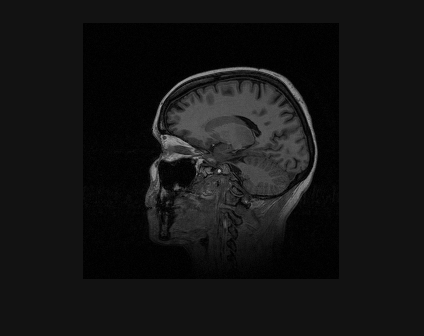

subplot(111)
imshow(X)

### Ajustando el brillo de una imagen

El brilo se puede ajustar moviendo el valor promedio de la imagen, con la suma de una constante a toda la imagen.

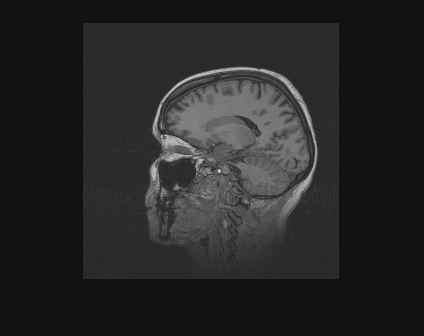

imshow(X+40)

## Contraste

El **contraste** mide la **diferencia relativa de intensidad** entre las regiones claras y oscuras de una imagen.

- Una imagen con **alto contraste** tiene zonas muy brillantes y muy oscuras bien diferenciadas.

- Una imagen con **bajo contraste** se ve “plana” o “lavada”, con poca diferencia entre intensidades.

- Matemáticamente, puede relacionarse con la **dispersión de los niveles de gris** (ej. la varianza o el rango dinámico).

- En imágenes médicas, mejorar el contraste facilita distinguir estructuras y tejidos que tienen intensidades similares (ej. distinguir órganos en una tomografía).

El contraste hace referencia al rango de valores que tiene una imagen 

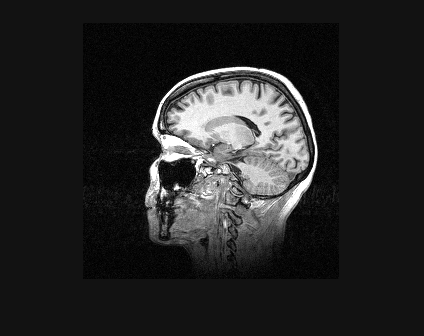


imshow(2.81*X + 0)

# Normalización de imagen

Para facilitar la visualización de imagen los valores de una imagen se escalan para ubicarlos dentro del rango [0,1]. Esto se logra mediante la siguiente ecuación:


$$X_{norm} = \frac{X - X_{min}}{X_{max}- X_{min}}$$


Donde $X_{min}$ corresponde al mínimo valor de la matriz y $X_{max}$ a suvalor máximo. Este proceso se llama *normalización* de la imagen. Una vez que la imagen está normalizada esta puede ser visualizada multiplicando por el valor de niveles de gris y redondeando al valor más alto.


$$X_{img} = \left \lceil{X_{norm} \cdot N_{gris}} \right \rceil$$


X = double(X);
Xnorm = (X - min(X(:)))/(max(X(:))-min(X(:)));

colormap(gray(256))

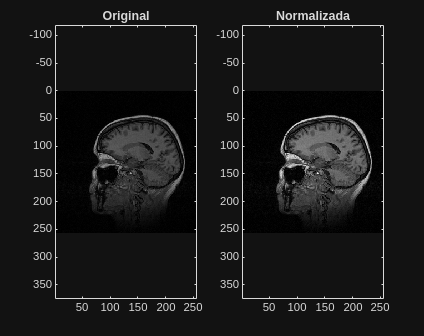

subplot(121)
image(X)
axis equal
title('Original')
subplot(122)
image(Xnorm * 256)
axis equal
title('Normalizada')

disp(['Valor mínimo: ', num2str(min(Xnorm(:)))])

Valor mínimo: 0


disp(['Valor máximo: ', num2str(max(Xnorm(:)))])

Valor máximo: 1


disp(['Valor medio: ', num2str(mean(Xnorm(:)))])

Valor medio: 0.1249


disp(['Desviación estándar: ', num2str(std(Xnorm(:)))])

Desviación estándar: 0.16628


La imagen normalizada puede fácilmente cambiarse a cualquier rango de niveles de gris usando la ecuación antes descrita:


$$X_{img} = \left \lceil{X_{norm} \cdot N_{gris}} \right \rceil$$


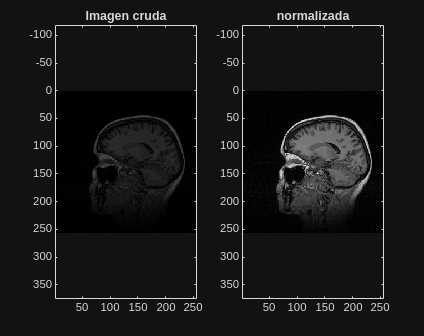

Ngris = 512;

colormap(gray(Ngris))
subplot(121)
image(X)
axis equal
title("Imagen cruda")
subplot(122)
image(ceil(Xnorm*Ngris))
title("normalizada")
axis equal

# Histograma

Un **histograma** es una representación gráfica de la **distribución de frecuencias** de un conjunto de datos.

- Se construye dividiendo el rango de valores en **intervalos (bins o clases)**.

- En el eje **x** se colocan los intervalos de valores.

- En el eje **y** se representan las **frecuencias** (absolutas o relativas) con las que ocurren los datos en cada intervalo.

- Sirve para **visualizar la forma de la distribución** (simétrica, sesgada, concentrada, dispersa, etc.).

El histograma se aplica a un conjunto de datos. Se estima su valor mínimo y máximo, así como su número de elementos, y estos valores permiten definir cuantas y cuales son las clases se deben formar. Esta representación permite visualizar cual es la distribución de los datos y conocer propiedades de este conjunto. En el caso de las imágenes médicas las clases son la profundida de color de la imagen y todos son de ancho uno, es decir se cuenta cada uno de los niveles de gris con los cuales está almacenada la imagen. Con lo cual se pueden distinguir los siguientes puntos clave.

- El histograma muestra la distribución de esos niveles de gris o colores.

- Permite describir características globales como **brillo, contraste y rango dinámico**.

- En imágenes médicas, el histograma es una herramienta para **evaluar la calidad de la imagen** y aplicar técnicas de **mejoramiento** (como ecualización de histograma) que realzan estructuras de interés.

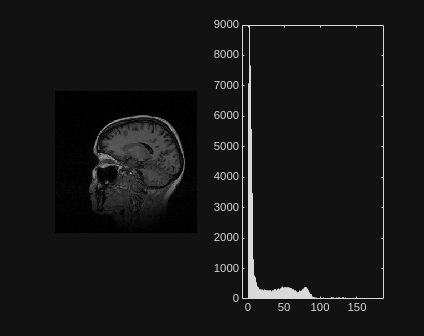

subplot(121)
imshow(X,gray(256))
subplot(122)
histogram(X(:),256)

Las modificaciones de brillo y contraste modifican la forma del histograma

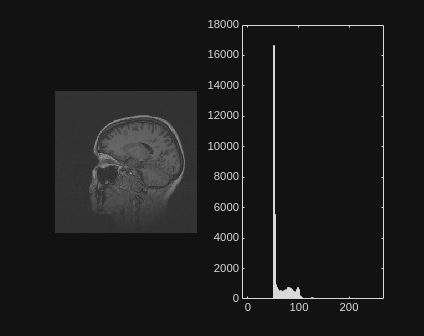

X_mod = 0.61*X + 50;
subplot(121)
imshow(X_mod,gray(256))
subplot(122)
histogram(X_mod(:),[1:256])

## Histograma de una imagen normalizada

Cuando la imagen está normalizada (en niveles de gris), esta ocupará el rango completo de valores dentro de la escala.

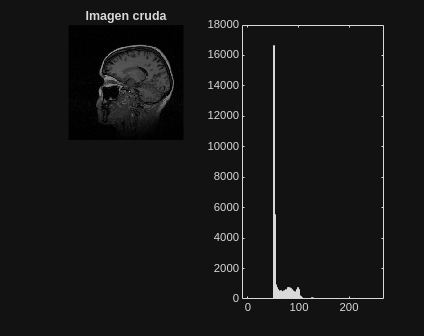

Ngris = 256;
X_mod = ceil(Ngris*Xnorm);

subplot(221)
imshow(X,gray(Ngris))
title('Imagen cruda')

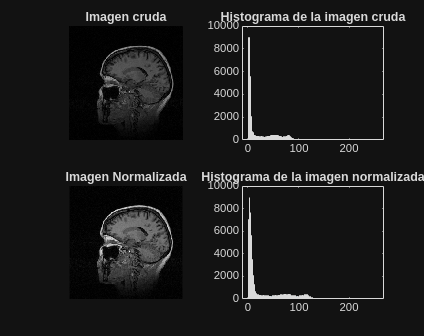


subplot(222)
histogram(X(:),[1:Ngris])
title('Histograma de la imagen cruda')

subplot(223)
imshow(X_mod,gray(Ngris))
title('Imagen Normalizada')

subplot(224)
histogram(X_mod(:),[1:Ngris])
title("Histograma de la imagen normalizada")

# Tipos de ruido aleatorio en imágenes

El ruido es un componente inherente a todo sistema de medición. El ruido de caracter aleatorio es un fenómeno que agrega a la imagen niveles de gris sobre algunos pixeles y que se desea eliminar. De forma matemática una imagen se puede entender de la siguiente manera: 


$$X_{acq} = X_{real} + X_\eta$$


Donde $X_{acq}$ es la imagen que se captura del equipo, $X_{real}$ es la imagen sin ruido o interferencia que se intenta capturar y $X_\eta$ es el proceso de ruido que viene de un fenómeno aleatorio. 

Los procesos aleatorios se caracterizan por la forma de distribución de sus datos. Entre los más frecuentes son:

#### Distribución uniforme


$$X_\eta \sim U(0,1)$$


Esta distribución indica que los pixeles se observan por igual porporción en el rango $0,1$. En el código se genera una imagen de puro ruido uniforme

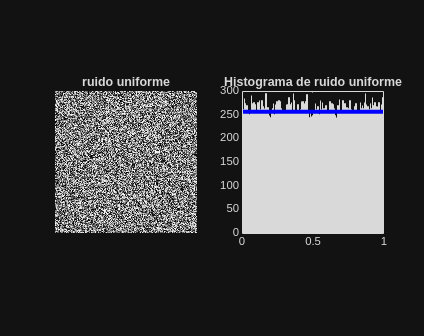

Ngris = 256;
Xunoise = rand(256);
subplot(121)
imshow(Xunoise*Ngris,gray(Ngris))
title('ruido uniforme')

subplot(122)
histogram(Xunoise,256)
hold on
plot([0,1],[256,256],'b','LineWidth',3)
hold off
title('Histograma de ruido uniforme')
axis square

#### Distribución Normal


$$X_\eta \sim N(\mu,\sigma) $$


Donde $\mu$ es el valor medio o central de la distribución y $\sigma$ es la desviación estándar del mismo.

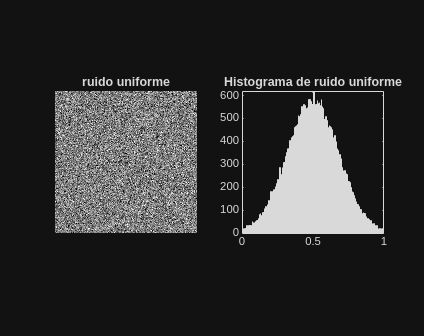

Ngris = 256;
Xunoise = randn(256);
mu = 0.5;
sigma = 0.18;
Xunoise = sigma* Xunoise + mu ;

subplot(121)
imshow(Xunoise*Ngris,gray(Ngris))
title('ruido uniforme')

subplot(122)
histogram(Xunoise,linspace(0,1,256))
title('Histograma de ruido uniforme')
axis square

#  Trabajo en clase

- Cargue la imagen "4.2.07.tiff" y estime el histograma para cada una de las capas de color.

- Cargue la imagen "aalcc.png", estime su histograma. Posteriormente normalice dicha imagen, muéstrela y vuelva a estimar el histograma.

- Realice lo mismo para la imagen "ct2.13.png".

- Use la imagen "ct2.13.png" y agregue ruido de tipo uniforme a la imagen normalizada y de tipo gaussiano con valores: $\mu=0.5$y $\sigma = 0.2$. A estas imágenes vuelva a estimar su histograma.